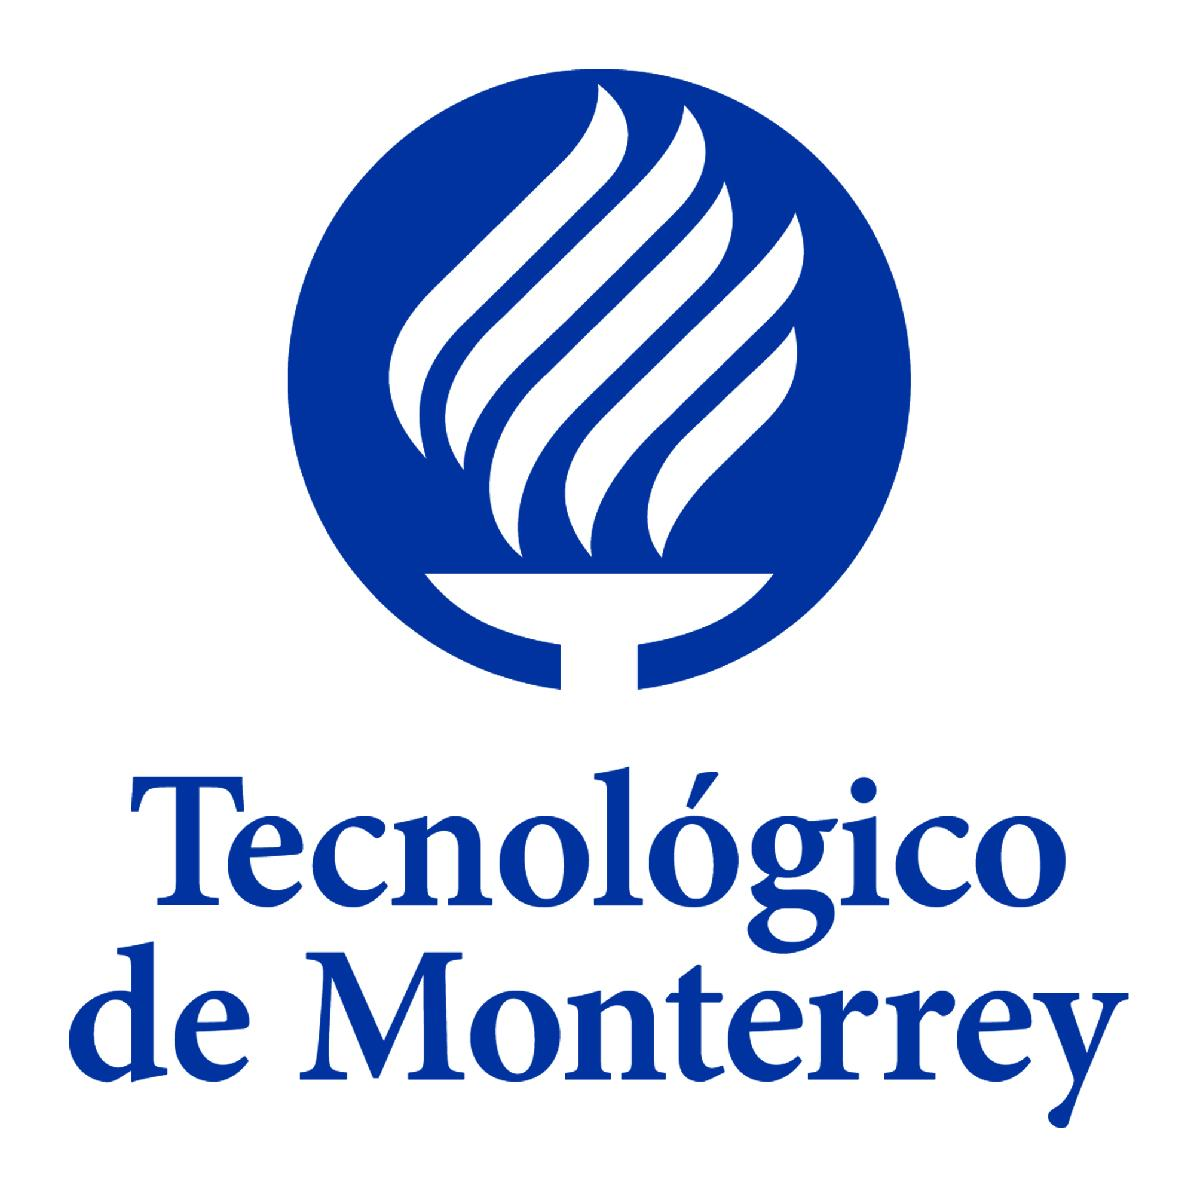 

**Simulador 3. Distancia entre cargas**

Presentado por:

Daniel Emilio Fuentes Portaluppi - A01708302

Profesor:

Ernesto Momox Beristain

F1013B Modelación computacional de sistemas eléctricos | Grupo 201

Viernes, 8 de abril del 2022

clc;
clear all;

Primero asignamos estas variables constantes, osea que no van a cambiar

%Constantes
g = 9.81;

Estos son tanto el tiempo en x como en y, le vamos a asignar 0 para poder calcularlo más adelante. 

C2 = 0; %Tiempo x
C4 = 0; %Tiempo y

Aquí se asignan los datos que quiera el usuario 

%Datos que asigna el usuario
E = input("Ingrese el campo eléctrico: ")

E = 500000

Qm = input("Ingrese Q/m: ")

Qm = 9.0000e-06

C1 = input("Ingresa tu velocidad inicial en el eje x: ")

C1 = 0

C3 = input("Ingresa tu velocidad inicial en el eje y: ")

C3 = 0

y = -(abs(input("Ingresa la altura a la que deseas saber la longitud (en m): ")))

y = -0.8000

Aquí se calcula el tiempo.

t = (C3 + sqrt(C3^2 - 2*g*y))/g

t = 0.4039

Para después sustituirlo en nuestra ecuación para calcular la distancia.

x = @(t) abs(((Qm * E * t^2)/2) + (C1 * t) + C2)

x = function_handle with value:
    @(t)abs(((Qm*E*t^2)/2)+(C1*t)+C2)


y = @(t) -g*(t^2/2) + (C3 * t) + C4

y = function_handle with value:
    @(t)-g*(t^2/2)+(C3*t)+C4



d = @(t) 2 * x(t)

d = function_handle with value:
    @(t)2*x(t)


x_text = "Tu distancia entre las cargas es " + d(t) + "m";
disp(x_text);

Tu distancia entre las cargas es 0.73394m


Gráfica en la que se puede ir viendo la caida de las cargas.

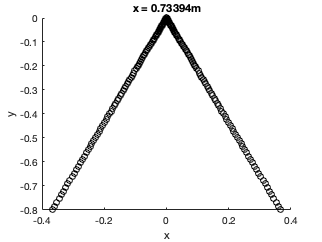

figure(1)
hold on
for i = linspace(0,t,100)
    plot(x(i),y(i), "ok")
    plot(-x(i),y(i), "ok")
    pause(0.001)
end
title(['x = ' num2str(d(t)) 'm'])
xlabel('x')
ylabel('y')
hold off

Grafica de **x** con respecto a **t**.

figure(2)
fplot(d)

title(['x = ' num2str(d(t)) ' m'])
grid
xline(0, 'k')
yline(0, 'k')

xlim([0 inf])
ylim([0 inf])